# Laboratorio 2 de Marzo del 2023, Análisis Aplicado, ITAM

## Prueba de Gradiente Conjugado

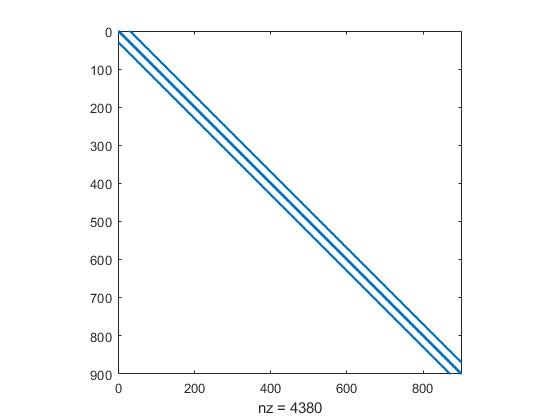

m = 30; % n = m^2
A = gallery('poisson', m);
spy(A)

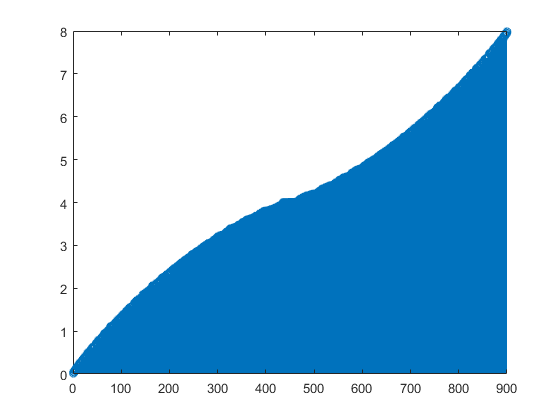

v = eig(A);
stem(v)


n = m^2;
b = ones(n,1);
[x,k] = migc(A,b);
k

k = 60


norm(A*x -b)

ans = 7.2925e-09

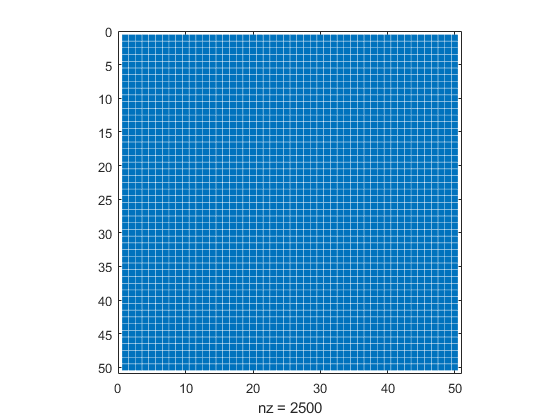



n = 50;
A = gallery('lehmer', n);
b = ones(n,1);
spy(A)

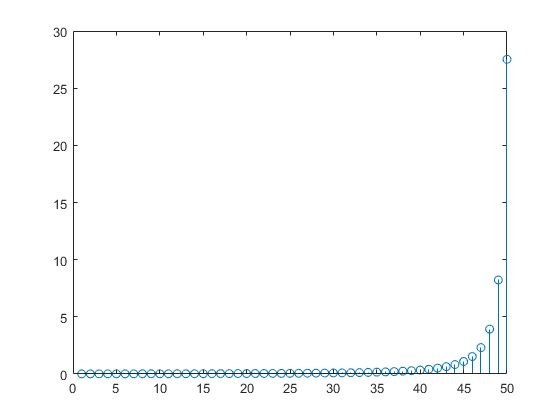

v = eig(A);
stem(v)

tic; [x,k] = migc(A,b); toc

Elapsed time is 0.002570 seconds.


k

k = 72


norm(A*x -b)

ans = 5.0079e-09



A = pascal(n);
tic; [x,k] = migc(A,b); toc

Elapsed time is 0.006168 seconds.


k

k = 2500


norm(A*x -b)

ans = 258.0177